# Kahan-family-optimal solution of OCI: Example 3.2

**Description**: Code to produce Example 3.2 of [1].

**Outputs**: none

**Assumptions and limitations**: none

**Other m-files required**: plotCov2.m, overlappingCI.m

**MAT-files required**: none

**Toolboxes required**: YALMIP [2], SDPT3 [3,4] (or MOSEK)

**Authors**: Leonardo Pedroso, Pedro Batista, W.P.M.H. (Maurice) Heemels

**Revision history**:

- 20/01/2025 - First draft of full implementation (Leonardo Pedroso)

- 01/12/2025 - Major revision (Leonardo Pedroso)

**References**:

[1] L. Pedroso, P. Batista, and W.P.M.H. Heemels, "Overlapping Covariance Intersection: Fusion with Partial Structural Knowledge of Correlation from Multiple Sources", 2025. (submitted)

[2] J. Lofberg, "YALMIP: A toolbox for modeling and optimization in MATLAB." In 2004 IEEE international conference on robotics and automation, pp. 284-289, 2004.

[3] K.C. Toh, M.J. Todd, and R.H. Tutuncu, SDPT3 — a Matlab software package for semidefinite programming, Optimization Methods and Software, 11 (1999), pp. 545–581.

[4] R.H Tutuncu, K.C. Toh, and M.J. Todd, Solving semidefinite-quadratic-linear programs using SDPT3, Mathematical Programming Ser. B, 95 (2003), pp. 189–217.

## Initialization

clear;
epsl = 1e-5;
% Colorblind-safe color palette (Wong, B. Points of view: Color blindness.
% Nat Methods 8,441 (2011). https://doi.org/10.1038/nmeth.1618)
color.black = [0 0 0]/255;
color.orange = [230 159 0]/255;
color.cyan = [86 180 233]/255;
color.green = [0 158 115]/255;
color.yellow = [240 228 66]/255;
color.blue = [0 114 178]/255;
color.red = [213 94 0]/255;
color.pink = [204 121 167]/255;


## Example 2D

% Seed
seed = 62038;
rng(seed);

% Sizes
n = 1;
m = 2;
o = 2; %(<= m)

% Generate bounds
M = 3;
Xb = cell(M,1);
Wb = cell(M,1);
Yb = cell(M,1);

% 1. Normal bound (X<= Xb1)
Xb{1,1} = 2*(rand(2,2)-0.5);
Xb{1,1} = Xb{1,1}*Xb{1,1}';
% In this case it is the same as Y1 = inv(X1)
Wb{1,1} = eye(2);
Yb{1,1} = (Wb{1,1}'/Xb{1,1})*Wb{1,1};

% 2. Bound on an principal component (X_11 <= Xb2_11)
Wb{2,1} = [1 0];
Xb{2,1} = (rand(1,1)-0.5);
Xb{2,1} = Xb{2,1}*Xb{2,1}';
% Equivalent to
% X2 = [1 0;
%       0 +inf]
Yb{2,1} = (Wb{2,1}'/Xb{2,1})*Wb{2,1};

% 3. Bound on an nonprincipal component (X_11 <= Xb2_11)
Wb{3,1} = [2 -1];
Xb{3,1} = 6*(rand(1,1)-0.5);
Xb{3,1} = Xb{3,1}*Xb{3,1}';
Yb{3,1} = (Wb{3,1}'/Xb{3,1})*Wb{3,1};

% Generate matrices H,C,R
H = 2*(rand(o,n)-0.5);
C = 2*(rand(o,m)-0.5);
R = 2*(rand(o,o)-0.5);
R = R*R';


## Overlapping CI

% Overlapping OCI w trace objective
[KOCItr,BOCItr,YOCItr,UOCItr] = overlappingCI(H,R,C,Yb,'trace');

MOSEK Version 10.1.21 (Build date: 2023-12-1 10:48:53)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: MACOSX/aarch64

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 5               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 9               
  Matrix variables       : 2 (scalarized: 9)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  :


BOCItr

BOCItr = 0.9248

KOCItr

KOCItr =     2.1535   -3.9684


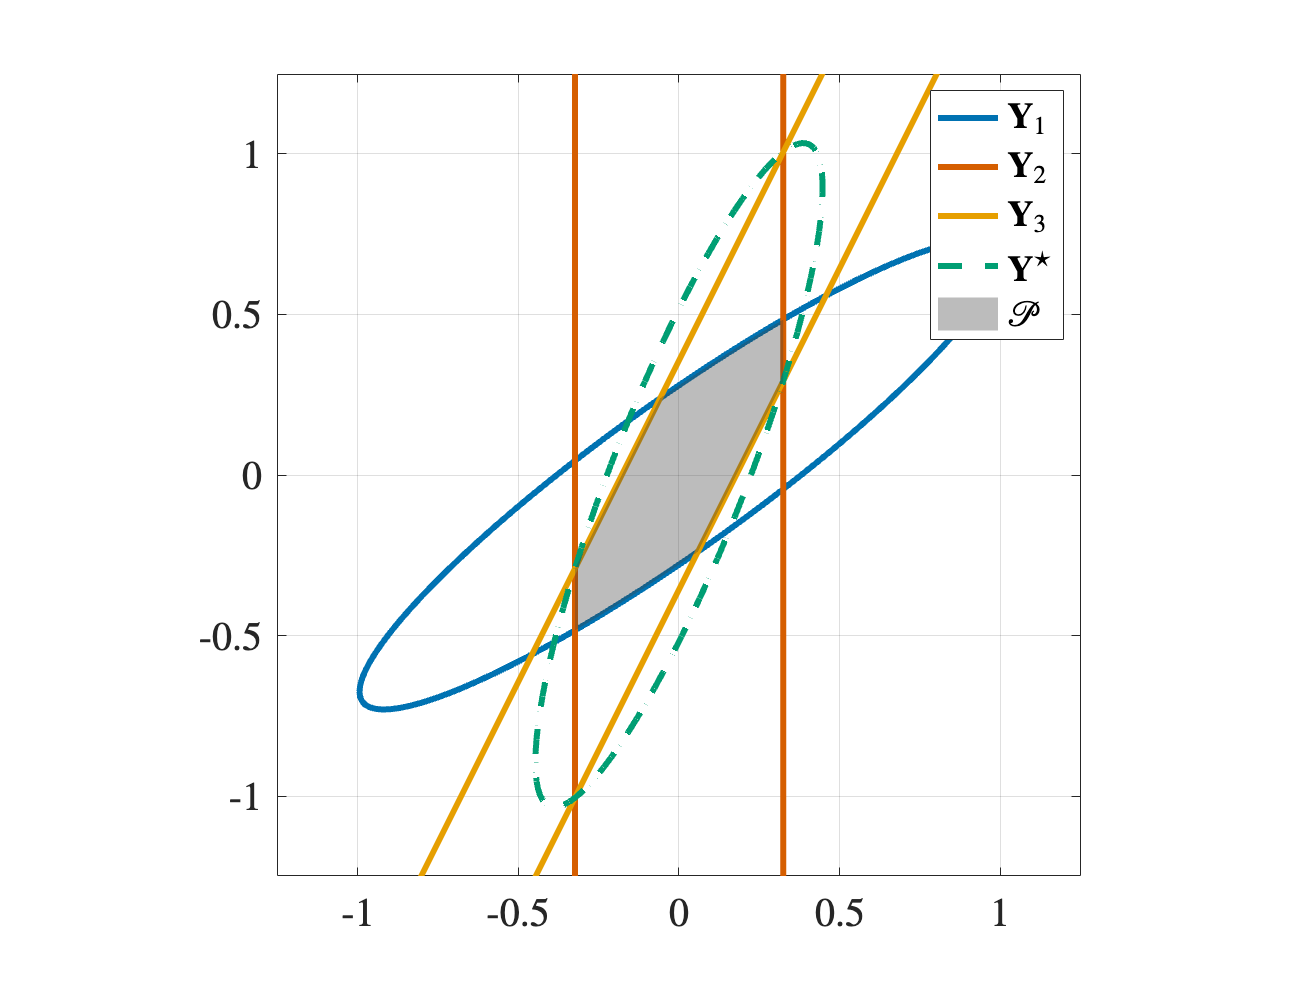


% Plot elipsoids
elpsXb1 = plotCov2(Yb{1,1});
elpsXb2 = plotCov2(Yb{2,1}+epsl*eye(2));
elpsXb3 = plotCov2(Yb{3,1}+epsl*eye(2));
elpsOCItr = plotCov2(YOCItr+epsl*eye(2));

poly1 = polyshape(elpsXb1(1,1:end-1),elpsXb1(2,1:end-1));
poly2 = polyshape(elpsXb2(1,1:end-1),elpsXb2(2,1:end-1));
poly3 = polyshape(elpsXb3(1,1:end-1),elpsXb3(2,1:end-1));
intersect12 = intersect(poly1, poly2);
intersect123 = intersect(intersect12, poly3);
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
plot(elpsXb1(1,:),elpsXb1(2,:),'LineWidth',3,'Color',color.blue);
plot(elpsXb2(1,:),elpsXb2(2,:),'LineWidth',3,'Color',color.red);
plot(elpsXb3(1,:),elpsXb3(2,:),'LineWidth',3,'Color',color.orange);
plot(elpsOCItr(1,:),elpsOCItr(2,:),'LineWidth',3,'Color',color.green,'LineStyle','--');
plot(intersect123, 'FaceColor', 0.25*[1 1 1], 'EdgeColor', 'none');
legend({'$\mathbf{Y}_1$','$\mathbf{Y}_2$','$\mathbf{Y}_3$','$\mathbf{Y}^\star$','$\mathcal{P}$'},'Interpreter','latex')
axis equal;
lim_axis = 0.25*max([max(elpsXb1(1,:)) max(elpsXb1(2,:))])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);


% Save figure to .fig and .pdf formats
% savefig('./figures/eg2_2D.fig');
% set(gcf,'renderer','Painters');
% exportgraphics(gcf,'./figures/eg2_2D.pdf');


## Comparison with SCI

% SCI bounds
X1_1_SCI = [1 0]*Xb{1,1}*[1;0];
Yb1_1_SCI = ([1 0]'/X1_1_SCI)*[1 0];
X1_2_SCI = [0 1]*Xb{1,1}*[0;1];
Yb1_2_SCI = ([0 1]'/X1_2_SCI)*[0 1];
X2_SCI = Xb{2,1};
Yb2_SCI = ([1 0]'/X2_SCI)*[1 0];

% one instance of SCI is just one instance of OCI but with more
% conservative bounds (cf. Remark )
Yb_SCI = cell(2,1);
Yb_SCI{1,1} = Yb1_2_SCI;
Yb_SCI{2,1} = Yb2_SCI;
[K_SCI,B_SCI,Y_SCI,U_SCI] = overlappingCI(H,R,C,Yb_SCI,'trace');

MOSEK Version 10.1.21 (Build date: 2023-12-1 10:48:53)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: MACOSX/aarch64

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 4               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 7               
  Matrix variables       : 2 (scalarized: 9)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  :

elpsSCI = plotCov2(Y_SCI+epsl*eye(2));

B_SCI

B_SCI = 4.8291

K_SCI

K_SCI =     2.3894   -3.6607


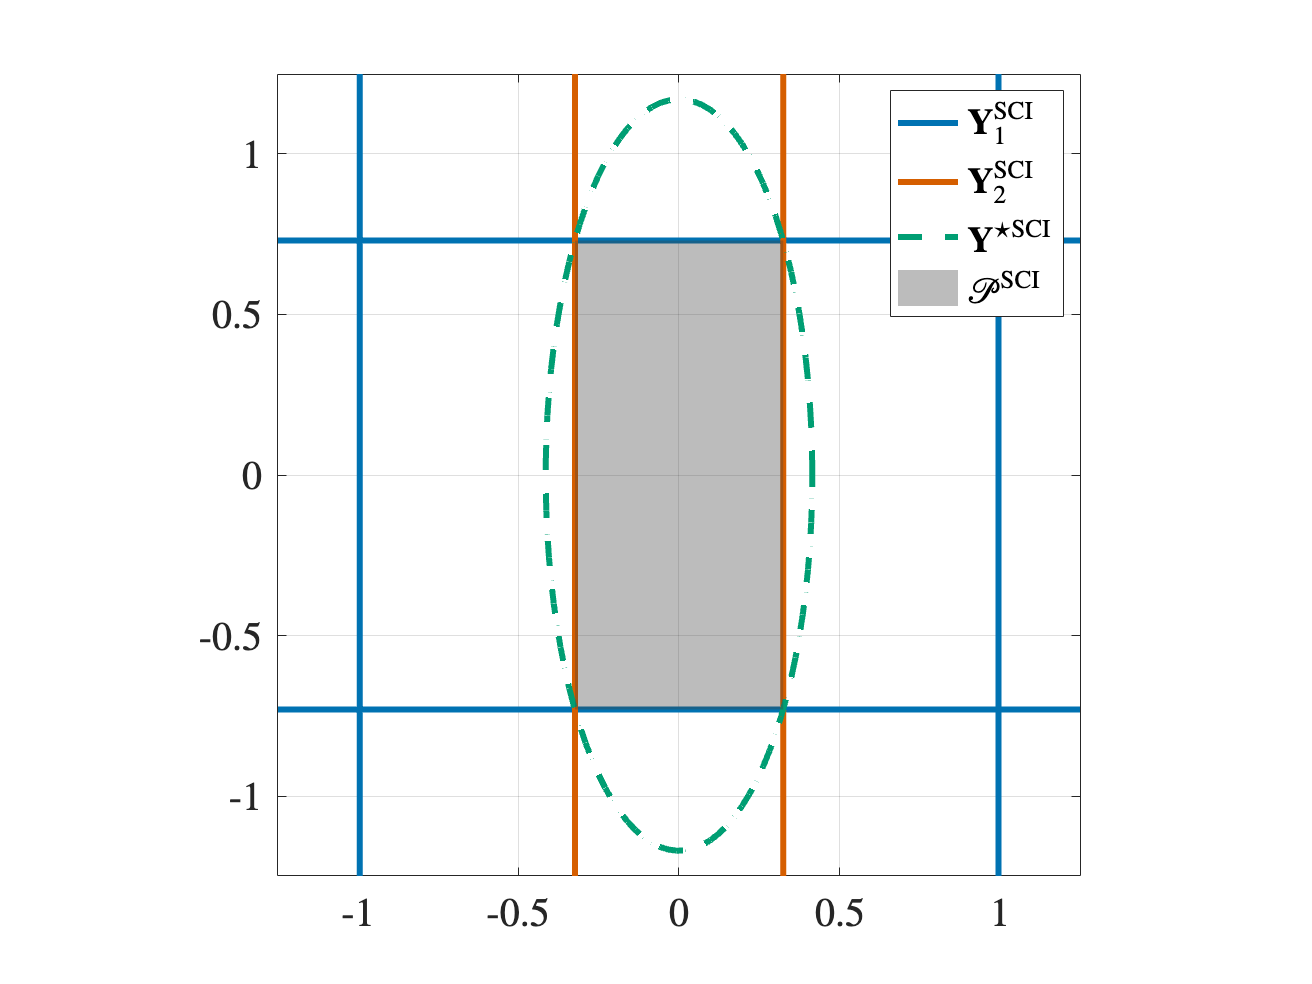


% Plot elipsoids
elpsX1_1_SCI = plotCov2(Yb1_1_SCI+epsl*eye(2));
elpsX1_2_SCI = plotCov2(Yb1_2_SCI+epsl*eye(2));
elpsX2_SCI = plotCov2(Yb2_SCI+epsl*eye(2));
poly1 = polyshape(elpsX1_2_SCI(1,1:end-1),elpsX1_2_SCI(2,1:end-1));
poly2 = polyshape(elpsX2_SCI(1,1:end-1),elpsX2_SCI(2,1:end-1));
intersect_SCI = intersect(poly1, poly2);
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
%plot(elpsXb1(1,:),elpsXb1(2,:),'LineWidth',3,'Color',color.blue);
plot(elpsX1_1_SCI(1,:),elpsX1_1_SCI(2,:),'LineWidth',3,'Color',color.blue);
plot(elpsX1_2_SCI(1,:),elpsX1_2_SCI(2,:),'LineWidth',3,'Color',color.blue,'HandleVisibility','off');
plot(elpsX2_SCI(1,:),elpsX2_SCI(2,:),'LineWidth',3,'Color',color.red);

plot(elpsSCI(1,:),elpsSCI(2,:),'LineWidth',3,'Color',color.green,'LineStyle','--');
plot(intersect_SCI, 'FaceColor', 0.25*[1 1 1], 'EdgeColor', 'none');
legend({'$\mathbf{Y}_1^{\mathrm{SCI}}$','$\mathbf{Y}_2^{\mathrm{SCI}}$','$\mathbf{Y}^{\star\mathrm{SCI}}$','$\mathcal{P}^{\mathrm{SCI}}$'},'Interpreter','latex')
axis equal;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);


% Save figure to .fig and .pdf formats
% savefig('./figures/eg2_2D_SCI.fig');
% set(gcf,'renderer','Painters');
% exportgraphics(gcf,'./figures/eg2_2D_SCI.pdf');
